# **Welcome to Deci**

**A fluid pipeline to analyze EEG Data with ease**

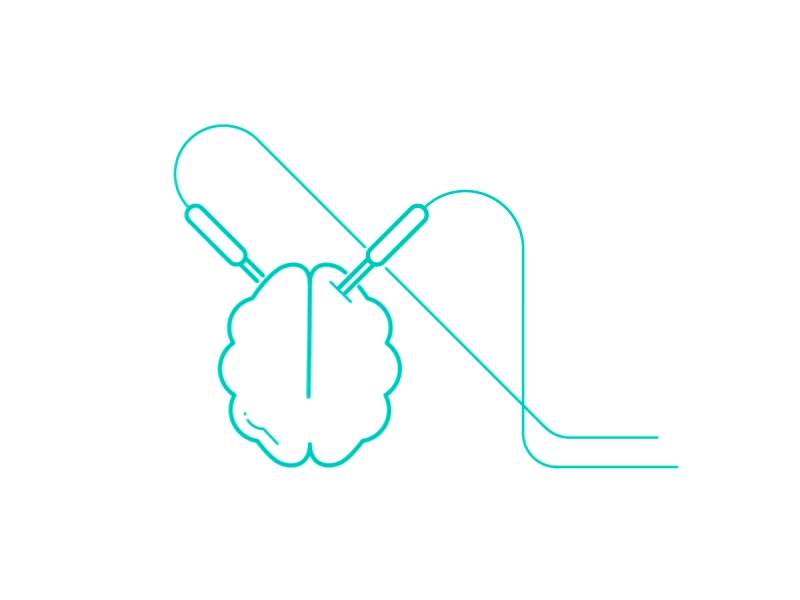

Written and Compiled by @John Nguyen of Robert Reinhart Lab on 10/15/2018, contact: Akida@bu.edu

## 0. MainMenu

Deci = [];
Deci.Folder.Raw         = ['C:\Users\User\Desktop\Shrey\Aging\RawData_new'];
Deci.SubjectList = 'gui';
Deci.Step               = 2;
Deci.Proceed            = false;
Deci.PCom               = true;   % Activates Parallel Computing (if availible)
Deci.Folder.Version     = ['C:\Users\User\Desktop\Shrey\Aging\ProcessedData'];

## 1. Trial Definitions

Deci.DT.Type       = 'LCM';
Deci.DT.Starts     = {192};         %Cell Array of Markers for ETs Start.
Deci.DT.Ends       = {193};         %Cell Array of Markers for ETs End.
Deci.DT.Markers    = {[10 11]  [100:102] [199:200] };
%                       L/R       H        RCor
Deci.DT.Locks      = [9 99 198];
%                     S1 S2 R
Deci.DT.Toi        = [-2 3];
% Cell Array of Markers for Block Starts

## 2. PreProcessing Steps

Deci.PP.filter.bpfreq = [1 50];
Deci.PP.filter.bpfilter = 'yes';
Deci.PP.filter.detrend = 'yes';

Deci.ICA.Automatic = false;

## 3. Artifact Rejection

Deci.Art.do = true;
Deci.Art.crittoilim = [-.5 1.5];
Deci.Art.RT.minlength = 200;
Deci.Art.RT.locks = [2 1];

## 4. Analysis


Deci.Analysis.Laplace       =false;                                                               % Uses Captrak .bvct file with same name in RawData Folder
Deci.Analysis.Locks         = [1 2 3];                                                          % Which Lock to Analyze
Deci.Analysis.LocksTitle    = {'Stim Onset' 'Rsp Onset' 'Fdb Onset'};                      % Folder Title to save each Lock as
Deci.Analysis.DownSample    = 500;

Deci.Analysis.Conditions    = {[300] [400]};
Deci.Analysis.CondTitle     = {'Congruent' 'Incongruent'};
Deci.Analysis.Version = [Deci.Folder.Version];

Deci.Analysis.HemifieldFlip.do = true;
Deci.Analysis.HemifieldFlip.Markers = [15 14];

Deci.Analysis.ERP.do  = true;


if Deci.Step == 4
    Deci.DT.Markers    = {[14 15] [300 400] [31 34] [1014 1015] [1300 1400] [1031 1034]};
    
    %Analysistypes = {'Exp_Analysis1', 'Exp_Analysis2'};
    %    for AnalysisLocks = Analysistypes
    %       eval(AnalysisLocks{1})
    Deci_Backend(Deci);
    %   end
end

## 5. Plotting



Deci.Plot.Version = [Deci.Analysis.Version];
Deci.Plot.Figures      = [true true ];
Deci.Plot.Math         = {'x2 - x1' 'x2 + x1'};           % Condition Math done after Bsl, Condition Indexes are appended on.
Deci.Plot.Draw         = {[1 2] [3]};                   % Cell array of Condition Index for each figure

Deci.Plot.Title        = {'All Trials' 'Incorrect - Correct'};          % Title for each figure
Deci.Plot.Subtitle     = {{'Correct' 'Incorrect'} {'Inc - Cor'}};     % Cell array of strings of subtitles for each Condition


Simon_Cor;

%Deci.Run.Freq =false;
Deci.Run.ERP =false;
Deci.Run.Extra = false;

Deci.Plot.BslRef = 'Stim Onset';
Deci.Plot.Lock =   'Stim Onset';

if  strcmpi(Deci.Plot.BslRef, 'Rsp Onset')
    Deci.Plot.Bsl     = [-.5 -.2];
else
    Deci.Plot.Bsl     = [-.2 0];
end

Deci.Plot.GrandAverage = true;

Deci.Plot.Freq.Topo.do    =false;
Deci.Plot.Freq.Topo.Toi     = [.2 .5];                   % Time of Interest
Deci.Plot.Freq.Topo.Channel = [{'FCz' 'Cz' 'Fz'}];                   % Channel of Interest

Deci.Plot.Wire.do    =false;
Deci.Plot.Wire.Toi     = [-.5 0];                   % Time of Interest
Deci.Plot.Wire.Channel = [{'PO7' 'PO8'}];              % Channel of Interest

Deci.Plot.Bar.do    =false;
Deci.Plot.Bar.Toi     = [-.5 -.4];                   % Time of Interest
Deci.Plot.Bar.Channel =  [{'PO7' 'PO8'}];            % Channel of Interest

Deci.Plot.Stat.do = true; % Will only work if for large subject pools
if Deci.Plot.Stat.do
    Deci.Plot.Stat.Type = 'Anova/T-test';
    Deci.Plot.Stat.alpha = .05;
end

if Deci.Step ~= 4
    
    Deci_Backend(Deci);
end

Running Deci for 6 subjects
 
Starting parallel pool (parpool) using the 'local' profile ...

